# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**September 16, 2024**

# PART 2 - Design of a Controller with Requirements on the Performance against Disturbances 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

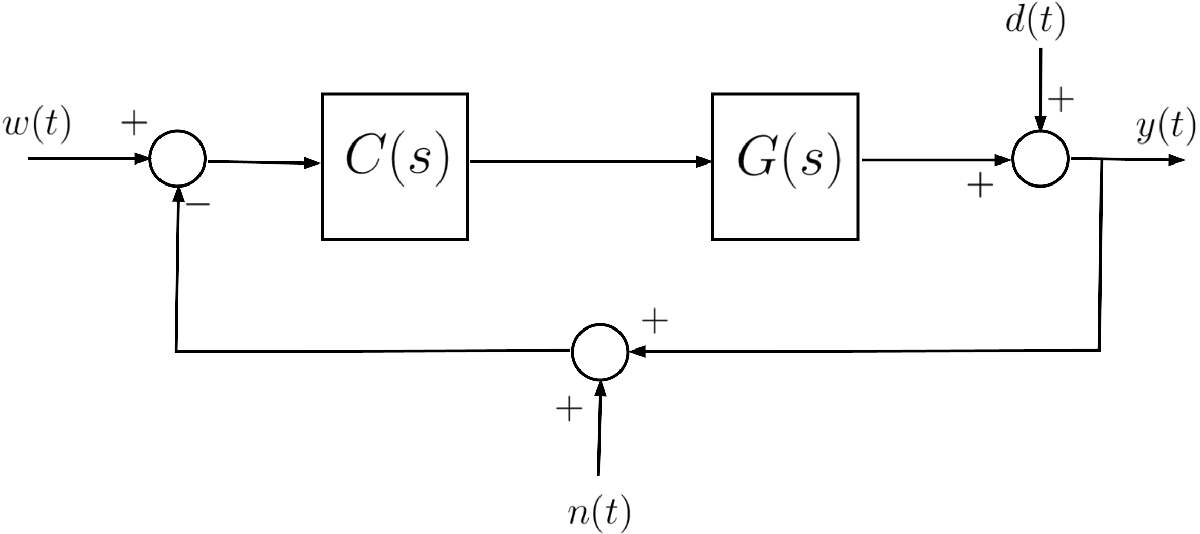	

where $G(s)$ is given by                


$$G(s) = 16\frac{(1+23s)}{(1+16\,s)\,(1+4s)}$$


### Assignment 		

**A1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $|e(\infty)|=0$ for $w(t) = \mathbf{1}(t)$;

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[0.001\,,\; 0.1\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/10$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[10,\,100\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/100$.	

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

The system described by the transfer function $G(s)$ is minimum-phase. Hence we proceed by a standard loop-shaping design of the controller $C(s)$through the following logical steps:

### Requirements Analysis

**Requirement (A1.2)**: The transfer function $T_{d,\,y}(s)$ from the input $d(t)$ to the output $y(t)$ is the sensitivity function $S(s)$ [refer to Part 9 of the course material, slides 34--36, 45--48]:


$$T_{d,\,y}(s) = S(s) = \frac{1}{1+L(s)}$$


Consider the frequency response associated with $T_{d,\,y}(s)$ and let's use the approximation introduced in Part 9 - Slide 48 of the course material:


$$\left\vert T_{d,\,y}(j \omega) \right\vert = \left\vert S(j \omega)\right\vert = \frac{1}{\left\vert 1+L(j\omega)\right\vert} \approx 
\left\{
\begin{array}{ll}
\frac{1}{\left\vert L(j\omega)\right\vert}\, , & \text{when } \left\vert L(j \omega) \right\vert \gg 1\\
1\, , &  \text{when } \left\vert L(j \omega) \right\vert \ll 1
\end{array} 
\right.$$


According to Req. (A1.2)


$$d(t) = D \sin \left(\bar{\omega}\,t\right) \cdot 1(t)\,,\quad \bar{\omega} \in \left[ \frac{1}{1000},\; \frac{1}{10} \right]$$


Hence, to obtain $\left\vert y_{d,\,\infty}\right\vert \le \frac{D}{10}$, we need to guarantee that $\left\vert S(j\,\bar \omega)\right\vert \le \frac{1}{10}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \ge 10,\; \forall \bar \omega \in \left[ \frac{1}{1000},\;\frac{1}{10}\right]$$


**Requirement (A1.3): **The transfer function $T_{n,\,y}(s)$ from the input $n(t)$ to the output $y(t)$ is the complementary sensitivity function $F(s)$ with a change of sign [refer to Part 9 of the course material, slides 34--36, 37--40]:


$$T_{n,\,y}(s) = -F(s) = -\frac{L(s)}{1+L(s)}$$


Analogously to what has been done above, consider the frequency response associated with $T_{n,\,y}(s)$ and let's use the approximation introduced in Part 9 - Slide 40 of the course material:


$$\left\vert T_{n,\,y}(j \omega) \right\vert = \left\vert F(j \omega)\right\vert = \frac{\left\vert L(j\omega)\right\vert}{\left\vert 1+L(j\omega)\right\vert} \approx 
\left\{
\begin{array}{ll}
1\, , & \text{when } \left\vert L(j \omega) \right\vert \gg 1\\
\left\vert L(j \omega)\right\vert \, , &  \text{when } \left\vert L(j \omega) \right\vert \ll 1
\end{array} 
\right.$$


According to Req. (A1.3)


$$n(t) = N \sin \left(\bar{\omega}\,t\right) \cdot 1(t)\,,\quad \bar{\omega} \in \left[ 10,\; 100 \right]$$


Hence, to obtain $\left\vert y_{n,\,\infty}\right\vert \le \frac{N}{100}$, we need to guarantee that $\left\vert F(j\,\bar \omega)\right\vert \le \frac{1}{100}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{100},\; \forall \bar \omega \in \left[10,\; 100\right]$$


**Requirement (A1.1): **This requirement implies that the **open-loop transfer function** should be of **type **$\mathbf{g=1}$. An integrator has to be added by the controller


$$C(s) = \frac{\mu_C}{s} \quad \Longrightarrow \quad L(s) = 16\,\mu_C \frac{(1+23s)}{s\,(1+16\,s)\,(1+4s)}$$


**Summing up**: we have obtained the following constraints on the transfer function $L(s)$ and on the Bode diagrams of the magnitude


$$\begin{array}{ccl}
\text{(A1.1)} & :& L(s) = 16\,\mu_C \frac{(1+23s)}{s\,(1+16\,s)\,(1+4s)} \\
\text{(A1.2)} & :&  \left\vert L(j\,\bar \omega)\right\vert \ge 10,\; \forall \bar \omega \in \left[ \frac{1}{1000},\;\frac{1}{10}\right] \quad \Longrightarrow \quad  \left\vert L(j\,\bar \omega)\right\vert \ge +20 \, \text{dB},\; \forall \bar \omega \in \left[ \frac{1}{1000},\;\frac{1}{10} \right] \\
\text{(A1.3)} & :&  \left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{100},\; \forall \bar \omega \in \left[ 10,\; 100\right] \quad \Longrightarrow \quad \left\vert L(j\,\bar \omega)\right\vert \le -40 \, \text{dB},\; \forall \bar \omega \in \left[ 10,\; 100\right] 
\end{array}$$


#### Design Strategy

Create the constraints on the magnitude $|L(j\omega)|$ in the Bode diagram using the **Control System Designer app, **or drawing "boxes" in the Bode diagram:

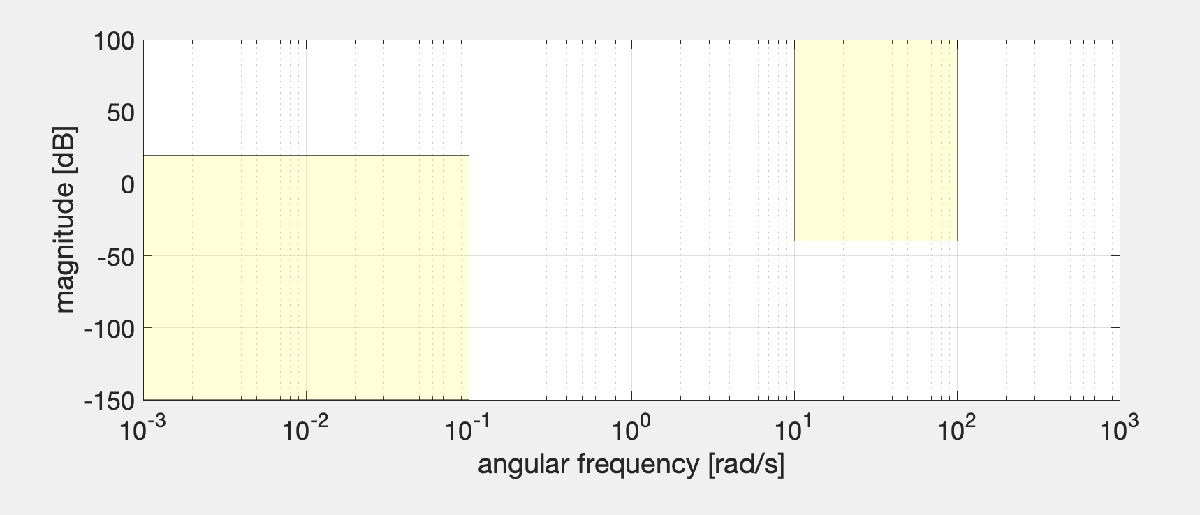

The **Bode** **diagram** of the **magnitude** $\left\vert L(j \omega)\right\vert_{\text{dB}}$ **should not cross these yellow regions**, and this graphical constraint provides valuable hints on the shape of the magnitude of the open-loop frequency response.				

As starting design configuration, let us set $\mu_C=1$ and check if $\left\vert L(j \omega)\right\vert_{\text{dB}}$ crosses the yellow regions. In case, modify $C(s)$ by adding zeros and/or additional poles.

### Answer to Question A1

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.		


$$G(s) = 16\frac{(1+23s)}{(1+16\,s)\,(1+4s)}$$


clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 16*(1+23*s)/((1+16*s)*(1+4*s)); % the process G(s)

As starting configuration, consider the simple controller


$$C_1(s) = \frac{1}{s}$$


muC = 1;
Cs = muC/s;

Ls = Cs * Gs


Ls =
 
      368 s + 16
  -------------------
  64 s^3 + 20 s^2 + s
 
Continuous-time transfer function.
Model Properties


#### First Approach: Using the Asymptotic Bode Diagrams

Let's draw the asymptotic and the effective Bode diagrams for $L(s)$

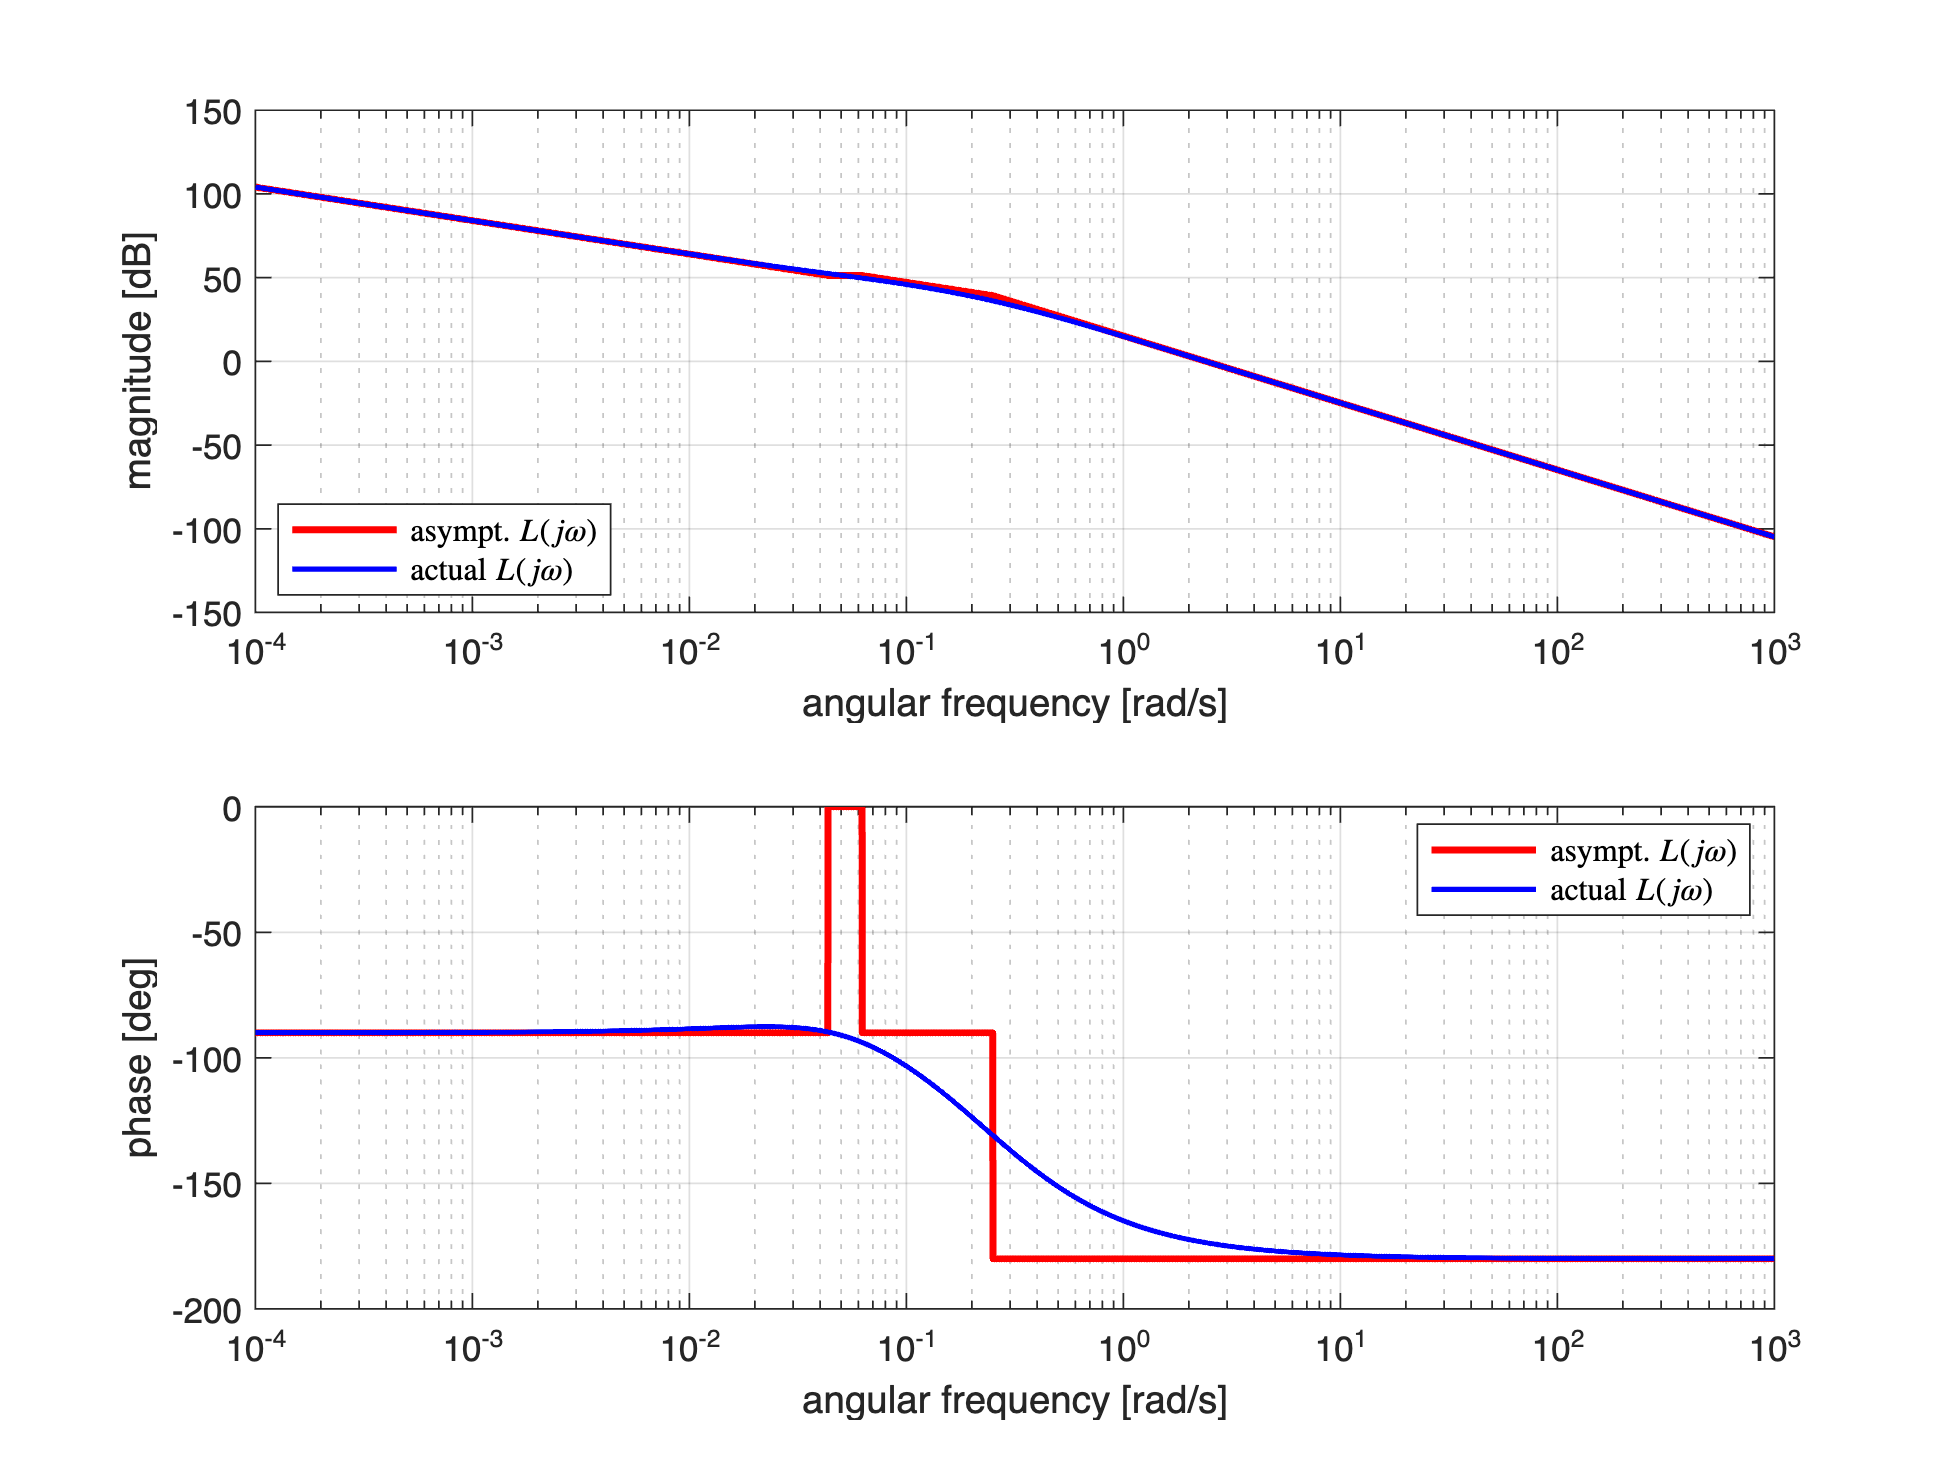

[ha1, ha2] = drawBodediagrams(Ls);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Let us add the constraints on the magnitude $\left\vert L(j \omega)\right\vert_{\text{dB}}$

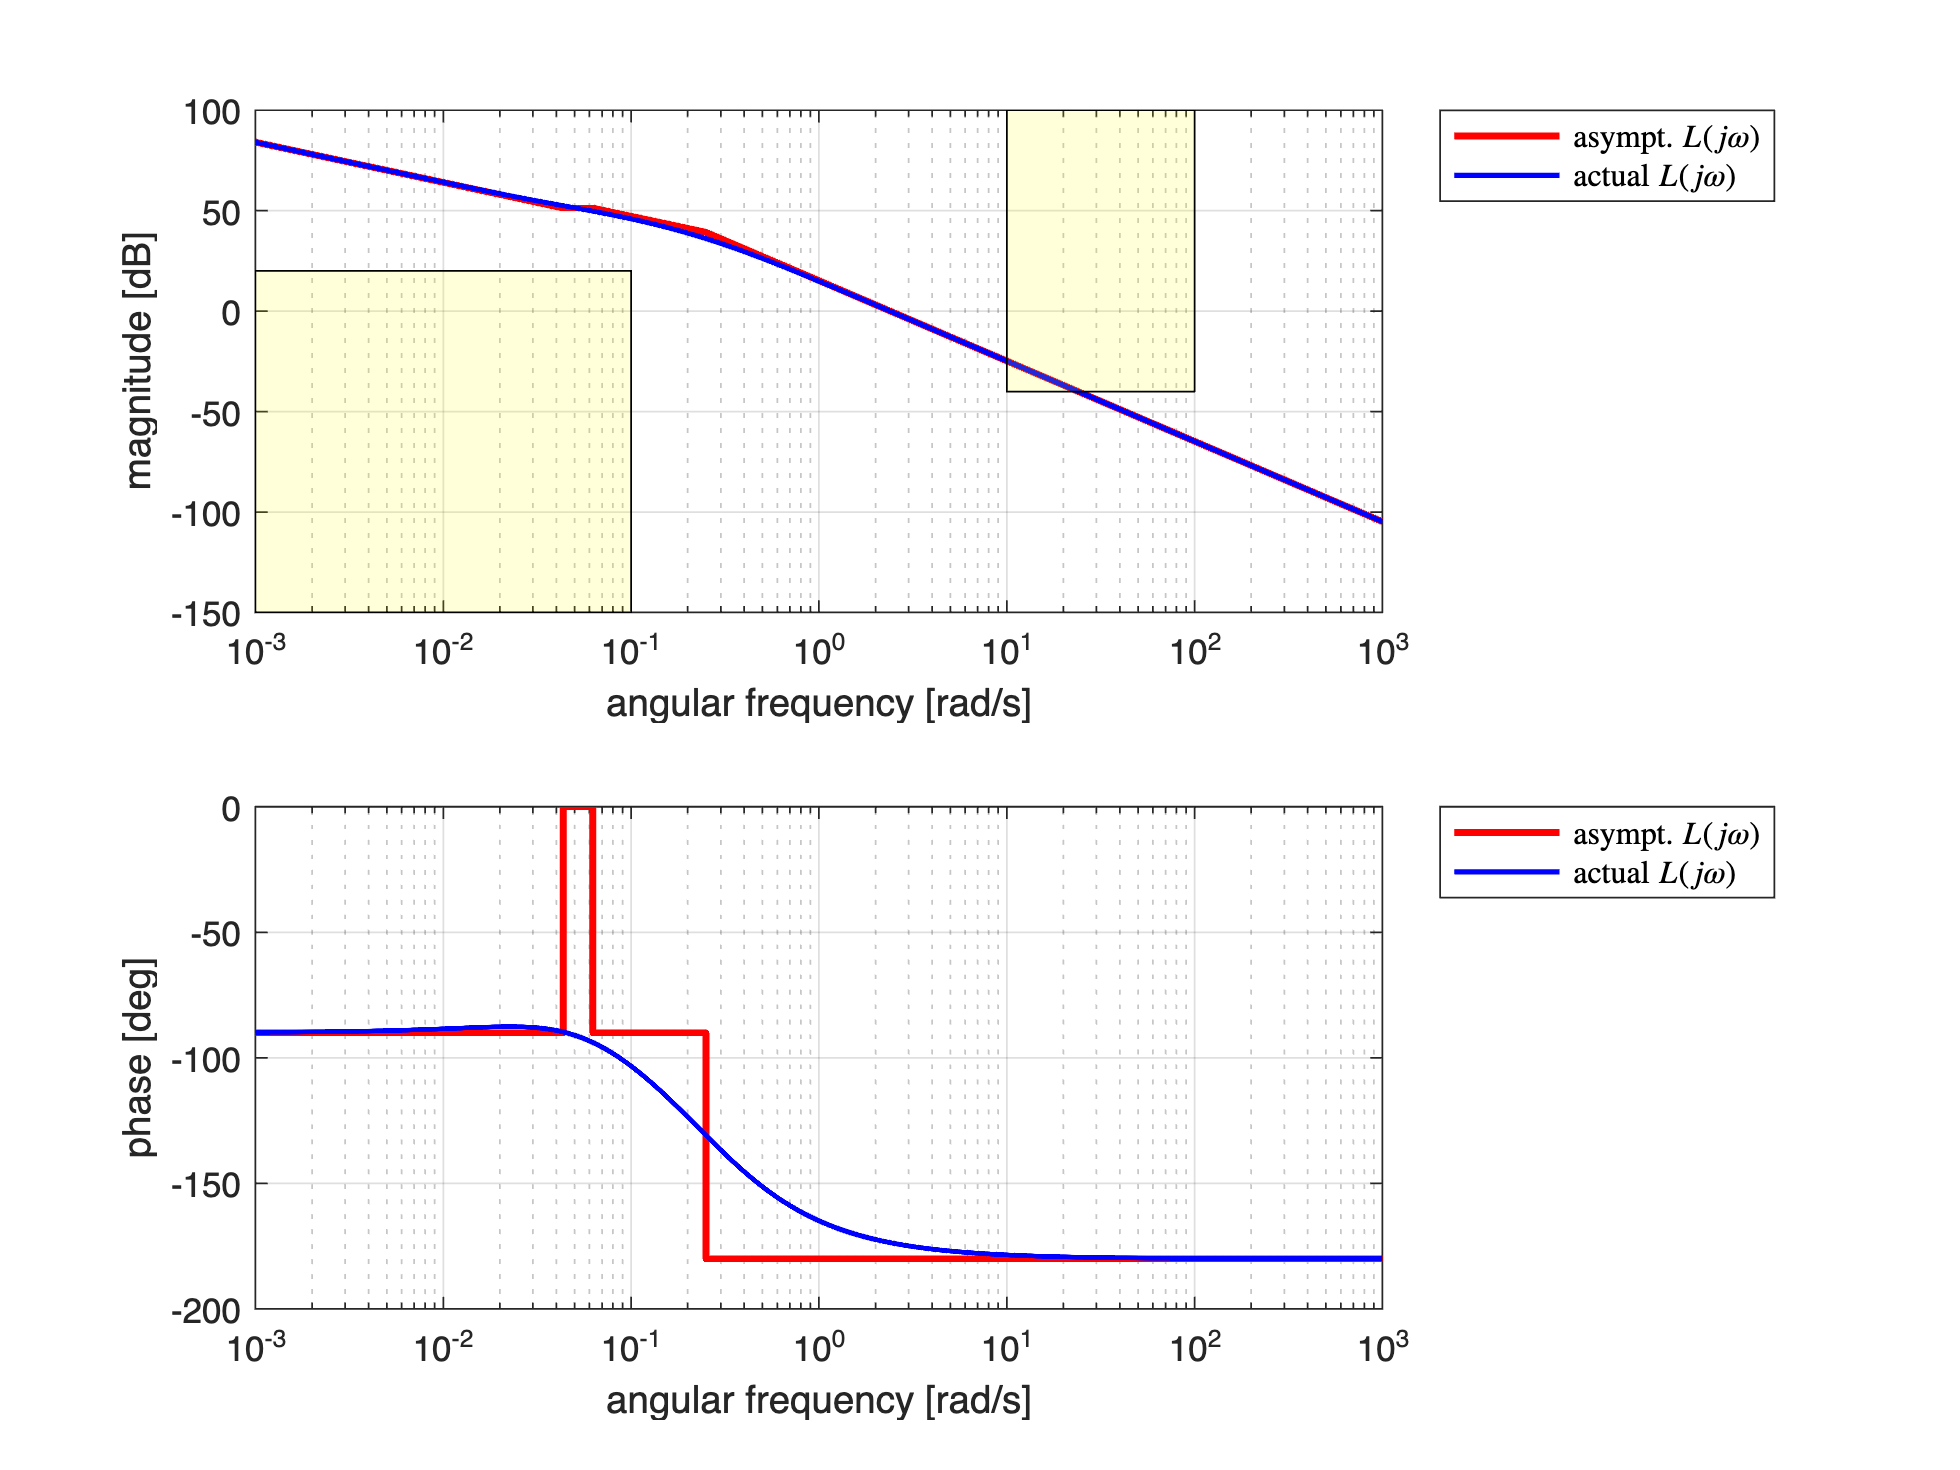

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-3, +3, 1e4); % 10000 values from 1e-3 up to 1e+3
[hax1, hax2] = drawBodediagrams(Ls, omVALS); % Bode diagram

% the (A1.2) constraint
minOmega1 = 0.001;
maxOmega1 = 0.1;
LMINdB = +20;
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (A1.3) constraint
minOmega2 = 10.0;
maxOmega2 = 100.0;
LMAXdB = -40;
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

Notice that setting $\mu_C = 1$does not meet the **requirements for the disturbance and noise attenuation**. Moreover, to fulfil those requirements we must modify the shape of $\left\vert L(j \omega)\right\vert_{\text{dB}}$.

#### Proposed Approach

- Let's delete the poles with time constants $\tau_1=16\,,\;\tau_2=4$;

- Delete also the zero with time constant $T=23$;

- Tune properly the gain $\mu_C$, in order to guarantee that $|L(j 0.1) | = + 20 \;\text{dB}$.

- Add another pole with time constant $\tau = 1$ to impose $|L(j 10) | = -40 \;\text{dB}$

Thus


$$\bar C(s) = \mu_C \frac{(1+16\,s)\,(1+4s)}{s\,(1+23\,s)\,(1+s)}$$


Preliminar Bode diagrams of the frequency response for $\bar L(j \omega) = \bar C(j \omega)\cdot G(j \omega)$


$$\bar L(j \omega) = \frac{16\,\mu_C}{s\,(1+s)}$$


Thus


$$\big\vert \bar L\left(j \frac{1}{10} \right) \big \vert = +20\;\text{dB} \; \Longleftrightarrow \; \frac{16\,\mu_C}{\frac{1}{10}\, \sqrt{1+\frac{1}{100}}} = 10 \; \Longleftrightarrow \;  \mu_C = \frac{1}{16}\, \sqrt{1+\frac{1}{100}}$$


muC = (1/16)* sqrt(1+0.01);
barCs = muC*((1+16*s)*(1+4*s))/(s*(1+23*s)*(1+s));

% Note: by using minreal() we force the simplification of common factors in
% the numerator and the denominator polynomials
barLs = minreal(barCs * Gs)


barLs =
 
   1.005
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


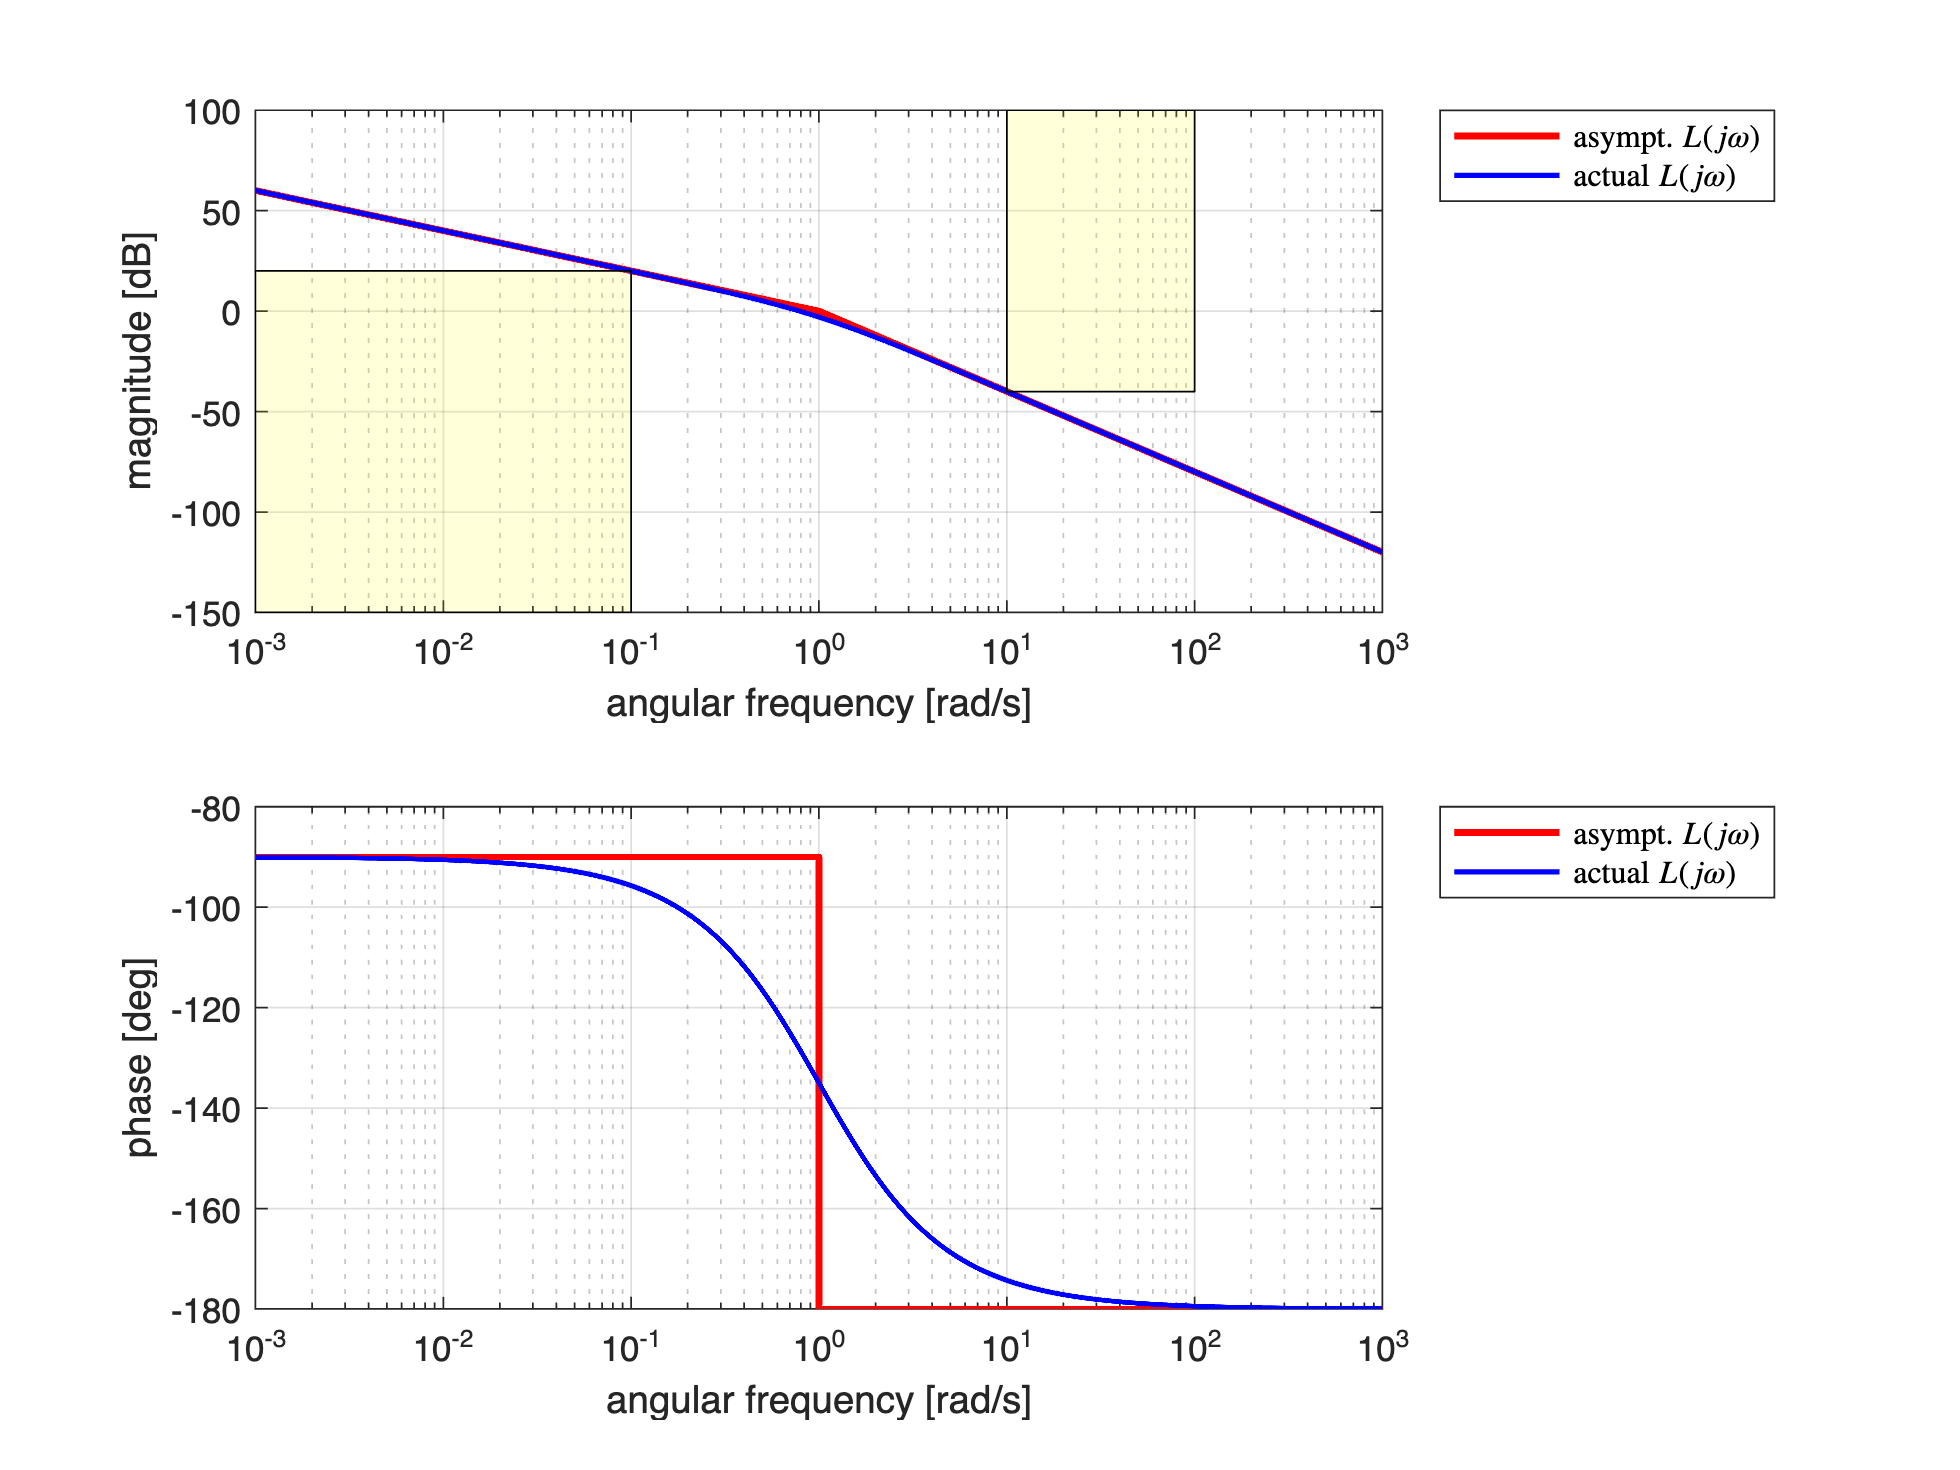

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-3, +3, 1e4); % 10000 values from 1e-3 up to 1e+3
[hax1, hax2] = drawBodediagrams(barLs, omVALS); % Bode diagram

% the (A1.2) constraint
minOmega1 = 0.001;
maxOmega1 = 0.1;
LMINdB = +20;
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (A1.3) constraint
minOmega2 = 10.0;
maxOmega2 = 100.0;
LMAXdB = -40;
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

Check if the magnitude constraints are met

% A1.2
( 20*log10( abs(freqresp(barLs, 0.1)) ) >= +20)

ans = logical
   1



% A1.3
( 20*log10( abs(freqresp(barLs, 10)) ) <= -40)

ans = logical
   1


Let's analyse the stability margins:

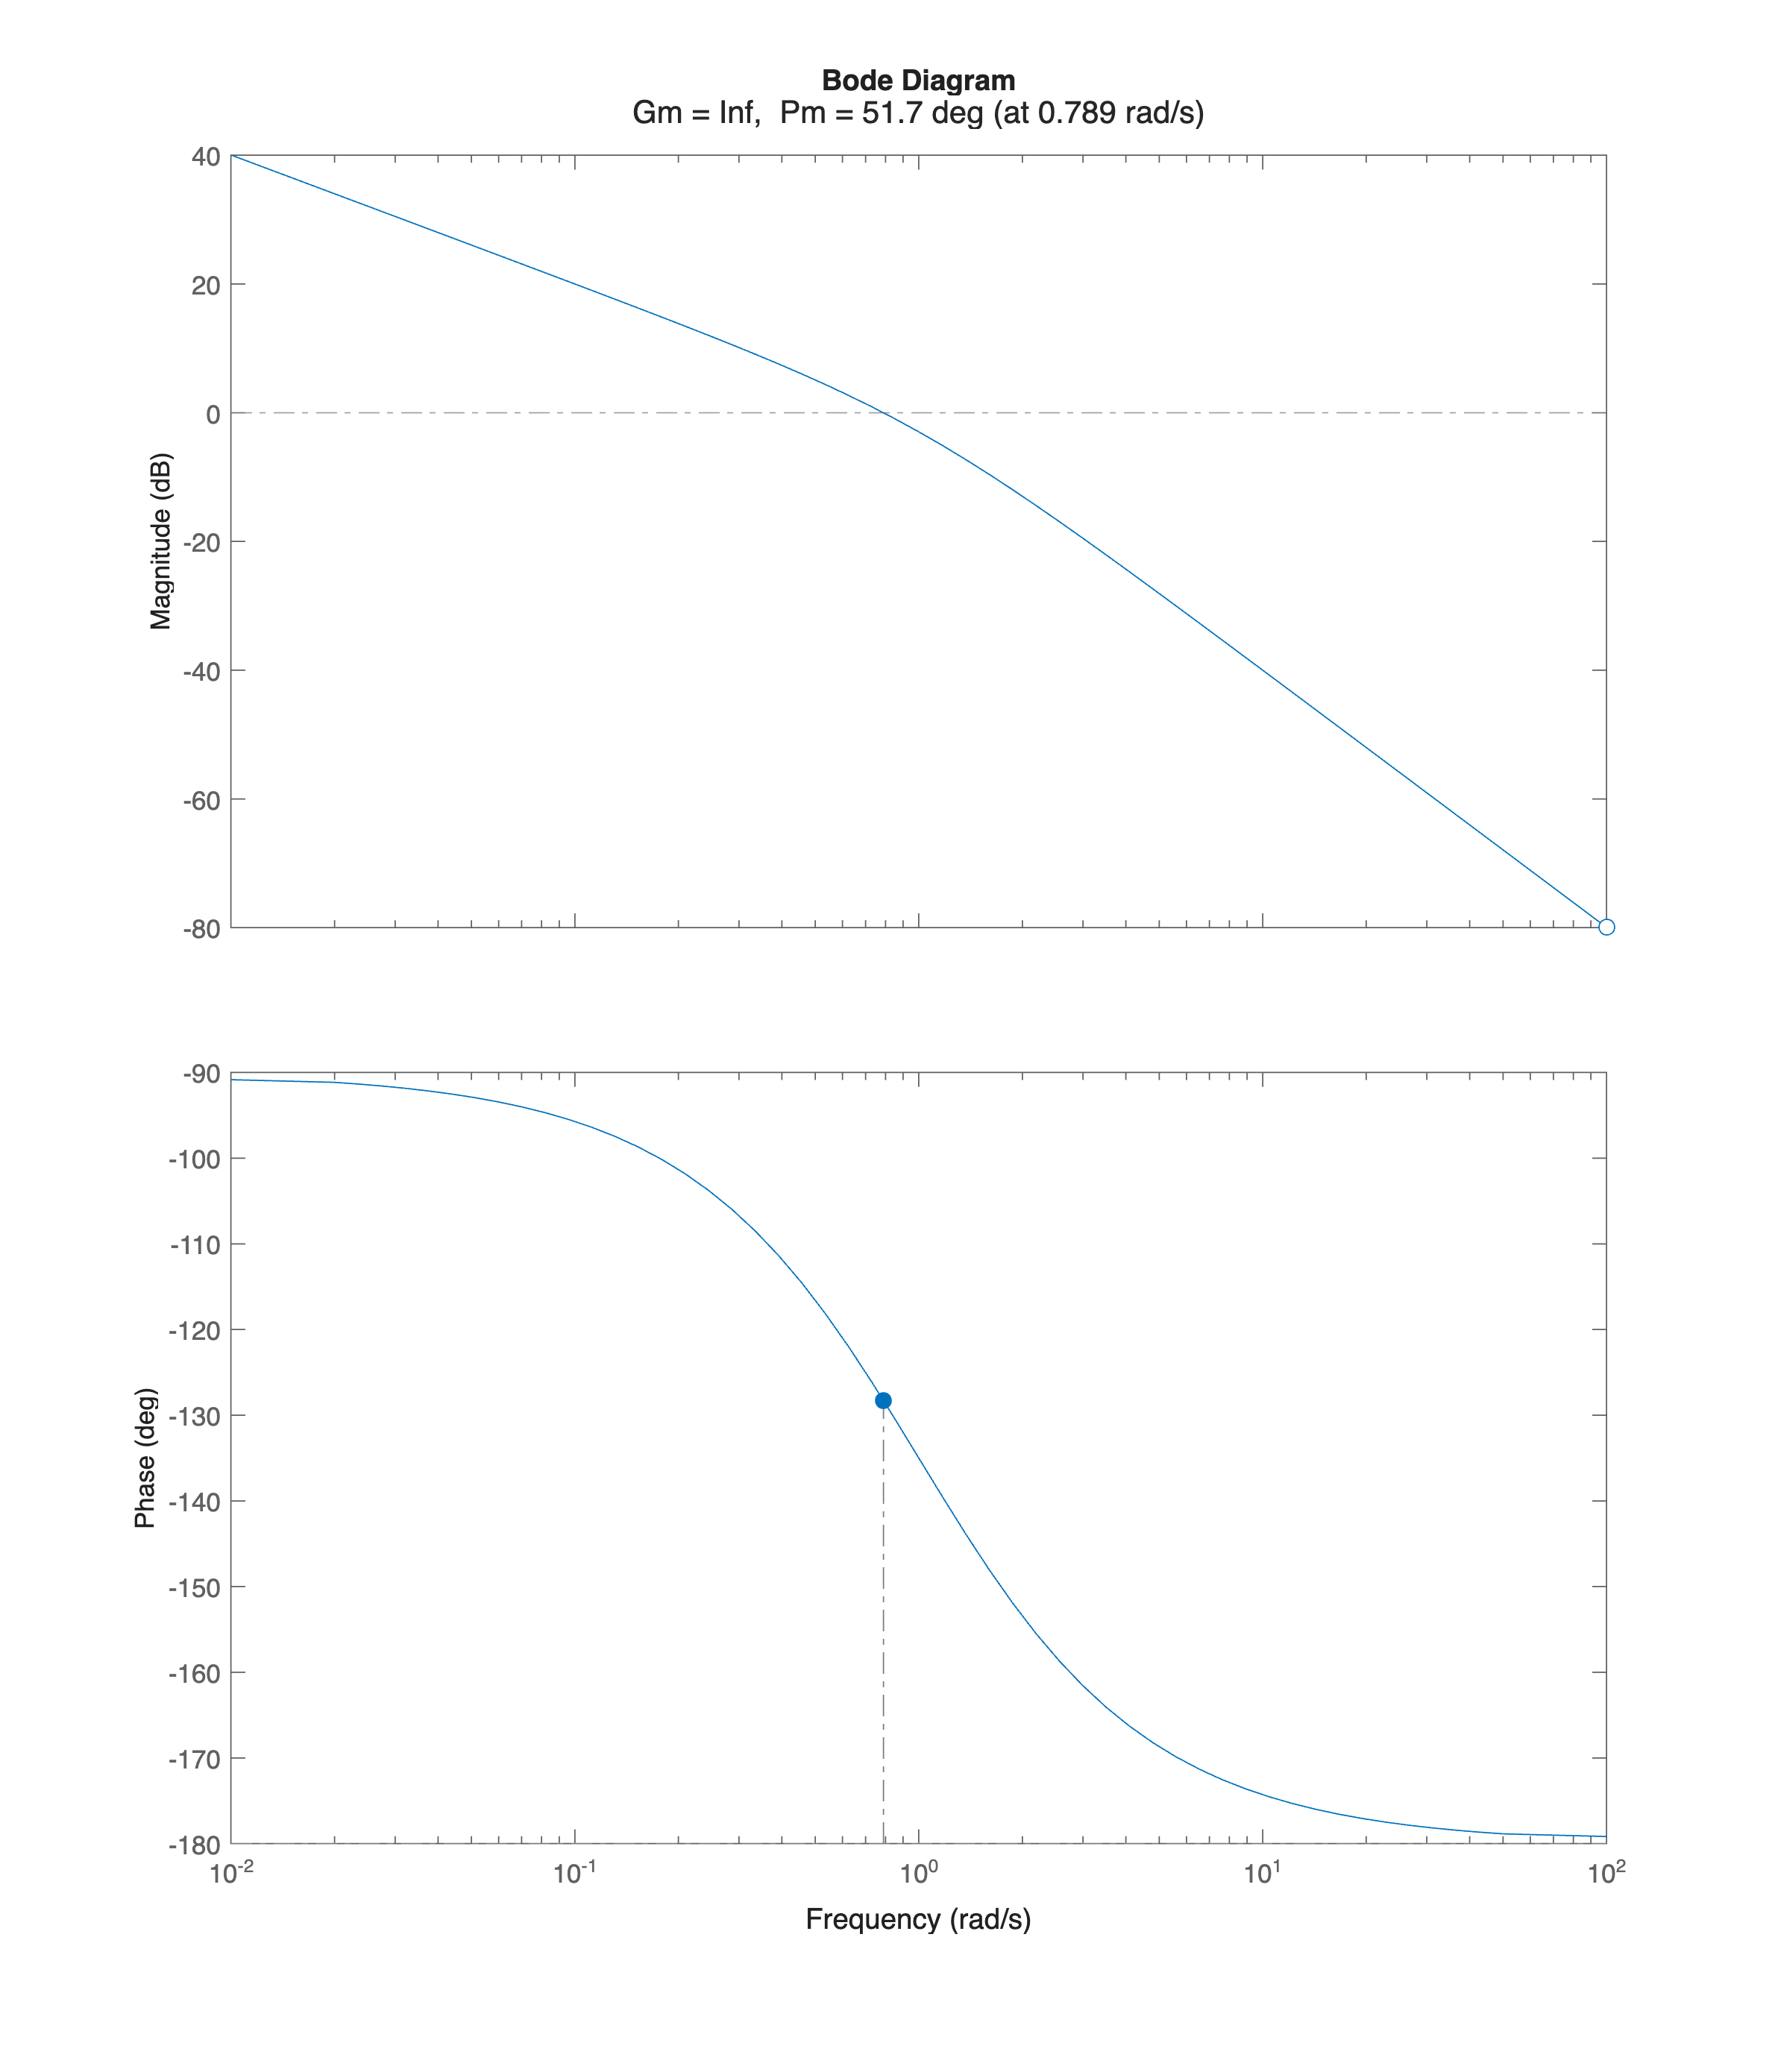

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

margin(barLs); 

The closed-loop system is asymptotically stable.

**All the requirements are met: the design has been completed.**

### **Fine Tuning using the Control System Designer App**

Let's analyse the control system performance using the controlSystemDesigner App:

controlSystemDesigner(Gs, barCs)

No need for further tuning.

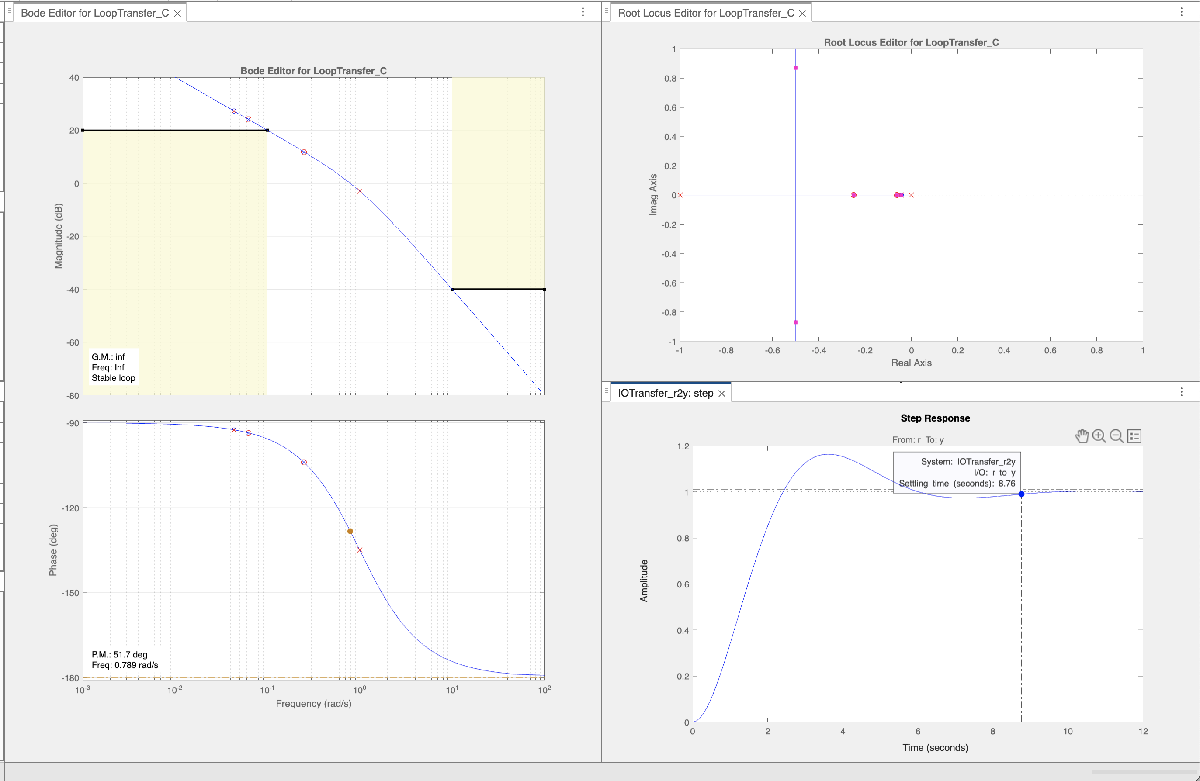

**Designer App session file**: `FA_24-09-16-ControlSystemDesignerSession.mat`